# Senzory a Měření - měření lineárního posuvu (LVDT, poťáky)

Vypracoval **Vojtěch Michal** 27. dubna 2021, "měření" provedeno dle videa ze dne 3.4. 2020.

Záznam z měření na Youtube:

[https://www.youtube.com/watch?v=cxkr9IbeMYo](https://www.youtube.com/watch?v=cxkr9IbeMYo) [https://www.youtube.com/watch?v=ZnYnIo-Iw2Q](https://www.youtube.com/watch?v=ZnYnIo-Iw2Q) [https://www.youtube.com/watch?v=wqjn_TITdB0](https://www.youtube.com/watch?v=wqjn_TITdB0) https://www.youtube.com/watch?v=gpLL9mnC_N0

Návod k úloze na Moodle: https://moodle.fel.cvut.cz/pluginfile.php/297268/mod_folder/content/0/07_linearni_posuv_2021_v3.pdf

## Domácí příprava

- Čemu se rovná výstupní odpor potenciometrického snímače polohy? (odporového děliče napětí, vzorec odvoďte, načrtněte graf) **Odpověď: **Základní pozorování: pro x = 0 nebo x = 1 (mezní polohy potenciometru) je vnitřní odpor tvořen pouze ochranným rezistorem. Pro x = 0.5 máme paralelně dvě větve s $\frac{R}{2}$ a k nim seriově ochranný odpor, což je dohromady odpor $\frac{R}{4} + R_0 = 1250 \Omega + 560 \Omega \approx 1800 \Omega$. Očekávám tedy parabolickou závislost $R_{in}$ na poloze $x$ (dále odvození viz obrázek).

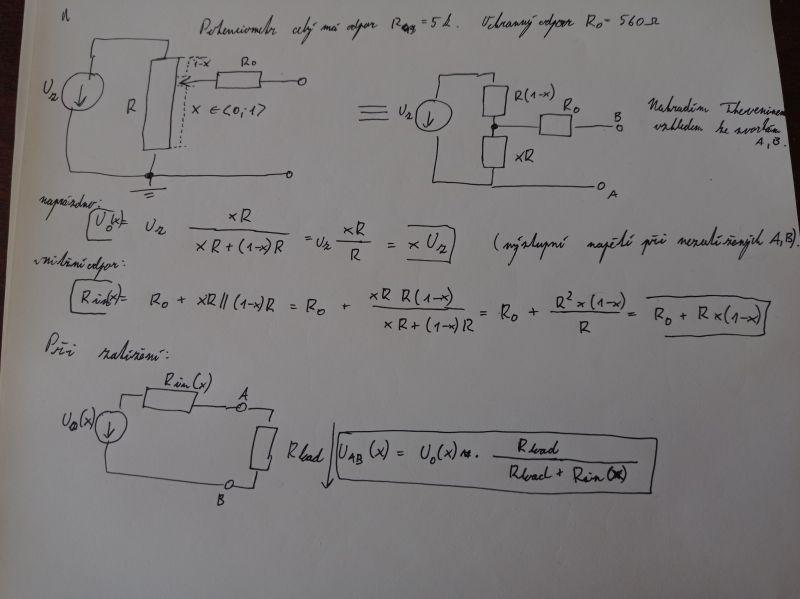

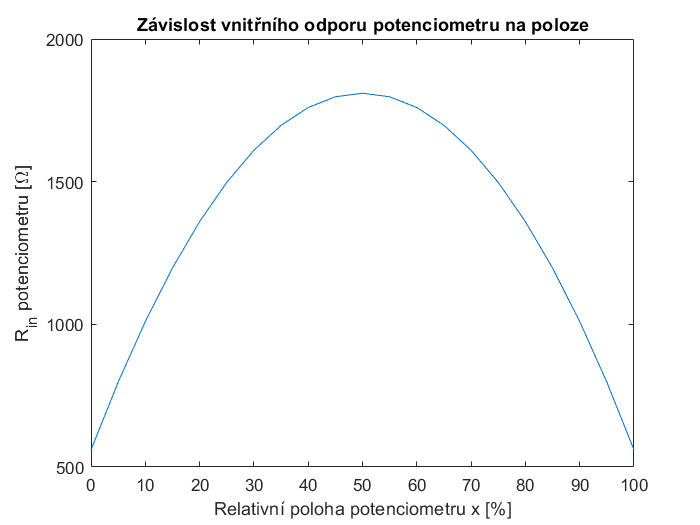

% Vykreslení grafů napětí a odporů na poťáku

R0 = 560; R = 5e3; Uz = 1; %Uvažujme Uz = 1V; stejně chceme jen tvar charakteristiky
x = 0:0.05:1; %vektor možných relativních poloh poťáku
Rin = x .* (1-x) * R + R0; %Vnitřní odpor Theveninovy náhrady potenciometru
U0 = x * Uz; %zdroj napětí v Théveninově náhradě

%Náčrt grafu vnitřního odporu
plot(x * 100, Rin);
xlabel('Relativní poloha potenciometru x [%]');
ylabel('R_{in} potenciometru [\Omega]');
title('Závislost vnitřního odporu potenciometru na poloze');

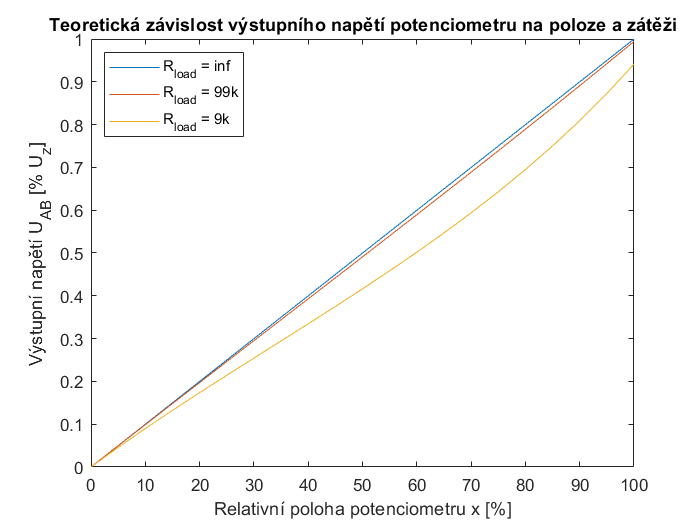


%Výstupní napětí se zátěží:
U_AB_inf = U0 * 10e6 ./ (10e6 + Rin); %použití napěťového sledovače za poťákem
U_AB_99 = U0 * 99e3 ./ (99e3 + Rin);
U_AB_9 = U0 * 9e3 ./ (9e3 + Rin);

plot(x * 100, U_AB_inf);
hold on;
plot(x * 100, U_AB_99);
plot(x * 100, U_AB_9);
legend('R_{load} = inf', 'R_{load} = 99k', 'R_{load} = 9k', 'Location', 'northwest');
xlabel('Relativní poloha potenciometru x [%]');
ylabel('Výstupní napětí U_{AB} [% U_z]');
title('Teoretická závislost výstupního napětí potenciometru na poloze a zátěži');


%Grafy potvrzují očekávání: s rostoucí zátěží svorek AB klesá linearita
%charakteristiky.

- Jak je určen u inkrementálního senzoru směr pohybu? **Opověď: **U inkrementálních senzorů je standardním výstupem kvadraturní signál - dva o 90° posunuté obdélníky na kanálech A, B. Nemá smysl hovořit o frekvenci, délka pulzů závisí na rychlosti pohybu. Směr otáčení jezdce je dán pořadím hran (například jen vzestupných, ale typicky citlivost na obě hrany) na kanálech A, B. Pakliže je signál A fazově před B, otáčí se senzor na opačnou stranu, než kdyby přišla hrana na B před hranou na A. Jednodušší než koukat na pořadí hran (třeba čítačem) je úplně přímočaře kontrolovat logickou úroveň obou signálů. Př: Detektor hran na kanálu A vyvolal interrupt kvůli náběžné hraně. Pakliže je B nahoře, potom jeho hrana již nastala dříve a je B před A. Pakliže je B dole, poté se B opožďuje za A.

- Proč nestačí výstupní napětí UO (anti-sériově zapojených sekundárů) u LVDT senzoru měřit střídavým voltmetrem a jaký přístroj lze použít? **Odpověď:** Výstupní napětí je rozdíl napětí na obou sekundárech. Ty jsou jistě na stejné frekvenci a ve fázi, takže rozdíl je zase sinusovka o stejné frekvenci, ovšem její fáze je závislá na tom, na kterém sekundáru je vyšší amplituda. Při průchodu střední polohou senzoru (výstupní napětí prochází nulou) se fáze skokově otáčí. Pro určení absolutní velikosti výchylky je potřeba určit amplitudu (či RMS) výstupního napětí, pro určení směru výchylky je potřeba detekovat fázi výstupu. Poslouží například synchronní detektor řízený z budicího napětí. Lze i jednodušeji, protože fázový posun není libovolný - vlny jsou vždy ve fázi a nebo v protifázi.

- Co to je raciometrická metoda a jaké jsou její výhody? **Odpověď: **Způsob zpracování signálu ze senzoru (nejen LVDT), kdy se obecně nějak normuje hodnota čtená ze senzoru. V případě LVDT se jedná o výpočet $\frac{U_A - U_B}{U_A + U_B}$, kde $U_A$, $U_B$ jsou napětí na sekundárech A, B. Díky normování je do značné míry eliminováno kolísání budicího napětí a není potřeba detekovat posun vůči primáru. Výpočet je realizován analogově/digitálně bezprostředně za senzorem samotným.

## Poznámky

Magnetický senzor - možná lineární i kruhová realizace. Na jedné straně (třeba na sledovaném objektu) je pásek s magnetickými doménami střídající se polarity nanesenými s mezerou např 2 mm (magnetické pravítko). Na druhé straně (třeba pevně na plošáku) je senzor snímající pole magnetické pole. Interpolací umí rozlišit 10 až 12 bitů polohy na každé "periodě" magnetického pravítka. To je rozlišení třeba 0.5 $\mu\text{m}$, které vysílá jkao PWM. Vedle toho má senzor standardní kvadraturní výstup, kterým se rozlišuje větší pohyb mezi doménami. Senzor bezkontaktní, velice přesný, umožňuje jistou vůli v nastavení vzdálenosti senzoru a pravítka a posunu v kolmém směru. Měří se čistě posun ve směru rovnoběžném s pravítkem.

Inkrementální senzory jsou inherentně relativní - v případě kvadraturního výstupu se dozvíme, že dochází k posunu o n segmentů doleva/doprava, ale nemáme ponětí, v jaké poloze se senzor spustil. Na pravítka (magnetická i pro optoelektronický snímač polohy) se proto běžně vynáší ještě *referenční značky,* které umožní přesně lopkalizovat alespoň jednu absolutní hodnotu. Tím se z inkrementálního senzoru dá dostat absolutní informace.

Odporový senzor polohy (potenciometr) je sice robustní a levný, ale je kontaktní, takže trpí na stárnutí materiálu (poškození jezdce, reznutí povrchu odporové dráhy, odskoky) a na nerovnoměrné jevy v odporové dráze, třeba nerovnoměrné zahřívání. Předejde-li se zatížení, je linearita velmi dobrá.

Optoelektronický senzor je bezkontaktní, obecně délka pravítka neomezená. Citlivý na vzájemnou polohu pravítka, stínítka a "vysílače" - při vzájemném posunutí v kolmém směru může světlo ze senzoru přestat procházet na stínítko.

LVDT je bezkontaktní (měřený objekt je připojen na jádro a to je v mezeře mezi vinutími), je velmi robustní, ale směrem ke krajům prudce roste nelinearita. Těžko si představit velmi dlouhé LVDT, proto měření spíše menších posunů. Pohybem jádra v rámci senzoru se nemění frekvence žádného ze signálů. Na výstupu se mění pouze amplitudy a případně fáze. Pohybem od středu do strany se mění vzájemná indukčnost primáru a každého ze sekundárů, roste proto amplituda napětí na tom sekundáru, ke kterému se jádro posouvá blíže.

## Úkoly měření

### A. Odporový senzor polohy (potenciometr)

Měření potenciometrem (Novotechnik TR100), za referenční senzor považujme optoelektronický snímač SL101LB, kterým jsou odměřeny polohy jezdce na odporové dráze (sloupec jedna následující tabulky). Potenciometr je napájen ze zdroje 5V Sloupce 2 až 4 jsou multimetrem měřená napětí na svorkách AB v závislosti na zátěži. Vstupní odpor multimetru předpokládáme nekonečný.

table = readtable('data_odporove.csv')

table = 11×4 table
    mm       oo       load99k      load9k 
    __    ________    ________    ________
     0      4.8292        4.79      4.4352
    10      4.3373      4.2839      3.8192
    20      3.8467      3.7865      3.2801
    30      3.3567      3.2964      2.7995
    40      2.8676      2.8127      2.3662
    50      2.3769       2.331      1.9576
    60      1.8863      1.8511      1.5633
    70      1.3954       1.372      1.1772
    80     0.90359     0.89074     0.78158
    90      0.4123     0.40805     0.37063
    98    0.020343    0.020186    0.019009

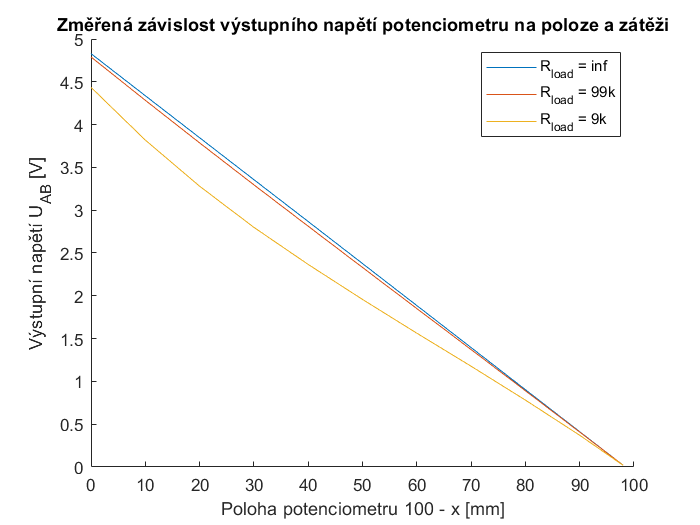

data = table2array(table);
distance = data(:,1);
load_inf = data(:,2);
load_99k = data(:,3);
load_9k = data(:,4);

%průběhy napětí
figure
hold on
plot(distance, load_inf);
plot(distance, load_99k);
plot(distance, load_9k);
legend('R_{load} = inf', 'R_{load} = 99k', 'R_{load} = 9k', 'Location', 'northeast');
xlabel('Poloha potenciometru 100 - x [mm]');
ylabel('Výstupní napětí U_{AB} [V]');
title('Změřená závislost výstupního napětí potenciometru na poloze a zátěži');

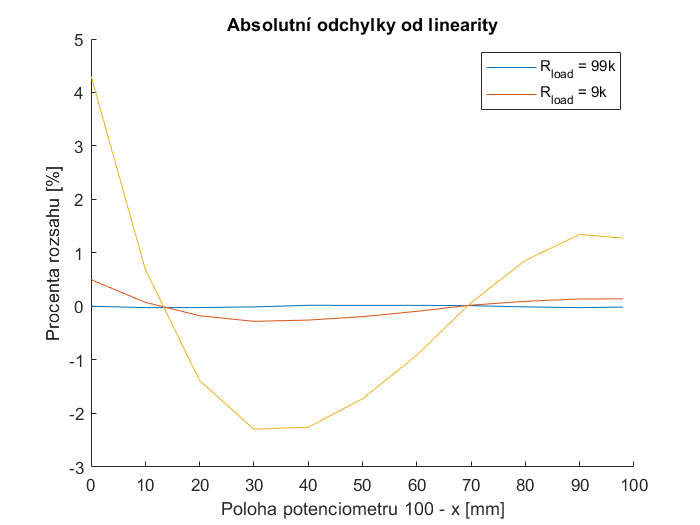


%vykreslení odchylek od linearity
fit_inf = fit(distance, load_inf, 'poly1');
fit_99k = fit(distance, load_99k, 'poly1');
fit_9k = fit(distance, load_9k, 'poly1');

figure
hold on
rozsah = 5; %napájení z pěti voltů
plot(distance, (load_inf - fit_inf(distance))/rozsah * 100);
plot(distance, (load_99k - fit_99k(distance))/rozsah * 100);
plot(distance, (load_9k - fit_9k(distance))/rozsah * 100);
legend('R_{load} = 99k', 'R_{load} = 9k', 'Location', 'northeast');
xlabel('Poloha potenciometru 100 - x [mm]');
ylabel('Procenta rozsahu [%]');
title('Absolutní odchylky od linearity');

Závěr je očekavatelný: zátěž nekonečným odporem je teoretické optimum, s rostoucí zátěží roste chyba nelinearity. Pozor: chyby nelinearity jsou vypočteny jako normovaný rozdíl měřených dat od přímky na ně fitnuté. Kdybychom vyšetřovali abolutní chybu např pro zátěž 9k od ideální charakteristiky (více méně dosažena přímkou pro nekonečnou zátěž), byla by chyba radikálně větší!

### B. Charakteristika LVDT snímače

Měřena byla hodnota na výstupu obvodu AD598 - ten zpracovává napětí $U_A$, $U_B$, raciometrickou metodou vypočte výraz (A-B)/(A+B) a následně jej vyhladí dolní propustí. Takovýto výstup je přibližně stejnosměrný, obsahuje velikost i znaménko (o znaménku nemá smysl hovořit u střídavého signálu, kde RMS je triviálně vždy nezáporná). Pro další zpracování je tak potřeba zařízení se symetrickým napájením schopné zpracovat i záporné napětí. Na následujícím grafu je vykreslena charakteristika LVDT. Pro snazší čitelnost je měření polohy jádra (původně v mm na intervalu [0, 100]) posunuto tak, aby se střed nalézal v nule.

dataGlobal = table2array(readtable('data_lvdt_global.csv'));
dataStred = table2array(readtable('data_lvdt_stred.csv'));

poloha = dataGlobal(:, 1);
napeti = dataGlobal(:, 2);

linearni_aproximace = fit(dataStred(:,1), dataStred(:,2), 'poly1');
% nalezněme polohu jádra, pro kterou je linearni_aproximace p1*x+p2 nulová
stred_LVDT = -linearni_aproximace.p2/linearni_aproximace.p1 %vychází 42 mm

stred_LVDT = 42.3320

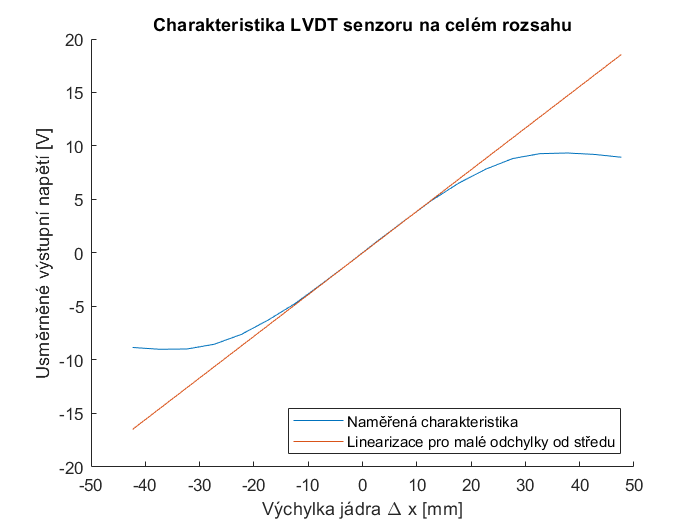

figure
hold on
%Pro vykreslení normujme polohu na ose x
plot(poloha - stred_LVDT, napeti);
plot(poloha - stred_LVDT, linearni_aproximace(poloha));

legend('Naměřená charakteristika', 'Linearizace pro malé odchylky od středu', 'location', 'southeast');

xlabel('Výchylka jádra \Delta x [mm]');
ylabel('Usměrněné výstupní napětí [V]');
title('Charakteristika LVDT senzoru na celém rozsahu');

### C. Pro odporový senzor vyslovte závěr o vlivu vstupního odporu voltmetru na měření. 

Porovnání senzorů viz Poznámky.

Vliv odporu voltmetru na měření s potenciometrem je jedním slovem zanedbatelný. Protože reálné voltmetry mají odpor alespoň 1 M$\Omega$ a již pro zátěž 99k$\Omega$ je chyba měření od linearity menší jak jedno procento napříč celým rozsahem, je zátěž způsobená voltmetrem takřka zanedbatelná. Kdyby tomu tak nebylo, vždy se dá na potenciometr pověsit sledovač napětí a zdroj tím posílit.